% Create optimization variables
x2 = optimvar("x","LowerBound",-2.5,"UpperBound",2.5);
y2 = optimvar("y","LowerBound",-2.5,"UpperBound",2.5);

% Set initial starting point for the solver
initialPoint.x = repmat(-2,size(x2));
initialPoint.y = ones(size(y2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@objectiveFcn,x2,y2);

% Set nondefault solver options
options = optimoptions("fmincon","Display","iter","PlotFcn",...
    "optimplotfvalconstr");

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x, y

	minimize :
       log(((1 + (3 .* (y - (x.^3 - x)).^2)) + (x - 1.3333).^2))


	variable bounds:
       -2.5 <= x <= 2.5

       -2.5 <= y <= 2.5




Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.069603e+00    0.000e+00    2.917e+00
    1       2    1.567084e+00    0.000e+00    1.129e+00    2.213e+00
    2       3    8.437887e-01    0.000e+00    1.161e+00    1.001e+00
    3       4    7.819412e-01    0.000e+00    1.514e+00    8.235e-01
    4       5    5.769648e-01    0.000e+00    8.243e-01    7.410e-01
    5       6    3.362942e-01    0.000e+00    8.577e-01    2.679e-01
    6       9    2.761279e-01    0.000e+00    7.379e-01    1.460e-01
    7      10    2.117204e-01    0.000e+00    4.471e-01    1.124e-01
    8      11    1.210045e-01    0.000e+00    1.857e+00    4.412e-01
    9      12    7.687288e-02    0.000e+00    1.496e+00    1.874e-01
   10      13    3.306364e-02    0.000e+00    8.603e-02    1.169e-01
   11      14    2.618174e-02    0.000e+00    1.333e+00    2.155e-01
   12      15  

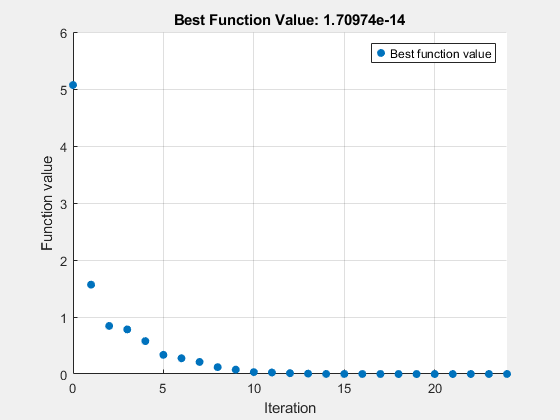


% Solve problem
[solution2,objectiveValue2,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);


% Display results
solution2

solution2 = struct with fields:
    x: 1.3333
    y: 1.0370


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue2

objectiveValue2 = 1.7097e-14


% Clear variables
clearvars x2 y2 initialPoint options reasonSolverStopped objectiveValue2

function objective = objectiveFcn(x, y)
% This function should return a scalar representing an optimization objective.

% Example: Concession stand profit
% revenue = 3*soda + 5*popcorn + 2*candy;
% cost = 1*soda + 2*popcorn + 0.75*candy;
% objective = revenue - cost; % profit

% Edit the lines below with your calculations.
objective = log( 1 + 3*(y - (x.^3 - x)).^2 + (x - 4/3).^2 );
end